clear
load mnist_28.mat

save mnist_28.mat

%selecting and saving images to train
numE = 400;
validP = 0.25;
idx1 = (training.labels == 1);
place1 = find(cumsum(idx1) > numE-1);
idx2 = (training.labels == 2);
place2 = find(cumsum(idx2) > numE-1);
idx4 = (training.labels == 4);
place4 = find(cumsum(idx4) > numE-1);
idx8 = (training.labels == 8);
place8 = find(cumsum(idx8) > numE-1);
images1 = training.images(:,:,idx1(1:place1));
images2 = training.images(:,:,idx2(1:place2));
images4 = training.images(:,:,idx4(1:place4));
images8 = training.images(:,:,idx8(1:place8));
trainingImages = cat(3, images1(:,:,1:(numE*(1-validP))), images2(:,:,1:numE*(1-validP)), images4(:,:,1:numE*(1-validP)), images8(:,:,1:numE*(1-validP)));
validationImages = cat(3, images1(:,:,(numE*(1-validP)+1):numE), images2(:,:,(numE*(1-validP)+1):numE), images4(:,:,(numE*(1-validP)+1):numE), images8(:,:,(numE*(1-validP)+1):numE));

trainingImagesNoised = trainingImages - randn(28)/7

trainingImagesNoised = trainingImagesNoised(:,:,1) =

   -0.2024    0.1474    0.0761    0.1409    0.0397   -0.0387    0.0899   -0.1101   -0.0174   -0.1444   -0.2123    0.0062    0.2832    0.1178   -0.1143    0.0416    0.0422   -0.0723   -0.1139   -0.1450   -0.0730    0.2255   -0.1974   -0.1235   -0.0508   -0.0038    0.0311   -0.0322
    0.0086   -0.1927    0.1565   -0.1649   -0.0931    0.0368   -0.1488    0.0756   -0.0877    0.0710    0.0068    0.1907   -0.0120    0.0905    0.1661    0.0717    0.2942   -0.0652   -0.1596    0.2029    0.0593   -0.0776   -0.0650   -0.0943    0.0005    0.0007    0.2186   -0.1571
   -0.1035    0.0433    0.1773   -0.1809   -0.0889   -0.1619    0.1419   -0.1565   -0.1724    0.0581   -0.1251    0.0966    0.0854   -0.0090    0.0446   -0.0470    0.2442    0.0327    0.0506   -0.0092    0.4805   -0.1059    0.0401    0.1388    0.0853    0.0380   -0.0443    0.0111
    0.3204    0.0765    0.2179   -0.0627    0.1534    0.1587   -0.2106    0.0559   -0.0625    0.1715   

delete('trainingImages2\*')
for k = 1:size(trainingImagesNoised, 3)
    imwrite(trainingImagesNoised(:,:,k),"trainingImages2\image"+num2str(k)+".png");
end

validationImagesNoised = validationImages - randn(28)/7

validationImagesNoised = validationImagesNoised(:,:,1) =

    0.1189    0.2347   -0.0350   -0.2730   -0.2649   -0.0874   -0.1575   -0.0496   -0.1701   -0.1049    0.0266   -0.0967   -0.3747   -0.1621   -0.0962    0.2982    0.0379    0.1222    0.2037    0.1476    0.0814   -0.1443    0.0899   -0.0037    0.0495   -0.2252   -0.0287   -0.0603
    0.0155   -0.0459    0.1038    0.0732    0.1110   -0.0136    0.0053    0.0133    0.0465   -0.0400    0.1649    0.0708   -0.1588    0.1108    0.2041   -0.0992   -0.0950   -0.0353   -0.1821   -0.2720    0.1065    0.2761   -0.2913    0.2271    0.1608   -0.0455   -0.1333   -0.1524
   -0.0011   -0.1990    0.1371   -0.0401   -0.0283    0.0987    0.2118   -0.0197    0.0181   -0.1485    0.0062    0.2284    0.0146   -0.0829   -0.0102   -0.0747    0.3360    0.0485    0.0029   -0.2073    0.1038   -0.2878   -0.0012   -0.2165    0.0700    0.0772    0.1907    0.0178
   -0.0533    0.1116   -0.0228    0.1881    0.0336   -0.0222    0.0990   -0.1240    0.1801    0.255

delete('validationImages2\*')
for k = 1:size(validationImagesNoised, 3)
imwrite(validationImagesNoised(:,:,k),"validationImages2\image"+num2str(k)+".png");
end

%creating imagedatastore from the files
imds = imageDatastore("trainingImages2\");
valds = imageDatastore("validationImages2\");

%creating a pixellabeldatastore
ldc = labelDefinitionCreator();
addLabel(ldc,'on',labelType.PixelLabel);
addLabel(ldc,'off',labelType.PixelLabel);
labelDefs = create(ldc);
clear pixelLabelImages
pixelIdx = trainingImages ~= 0;
pixelLabelImages(28,28,1:size(trainingImages, 3)) = 0;
pixelLabelImages(pixelIdx) = 1;
pixelLabelImages(~pixelIdx) = 2;
pixelLabelImages = uint8(pixelLabelImages);
clear dataFile;
dataFile(size(trainingImages, 3),1) = "a";

delete('pixelLabelImages2\*')
for k = 1:size(trainingImages, 3)
    imwrite(pixelLabelImages(:,:,k),"pixelLabelImages2\image"+num2str(k)+".png");
    dataFile(k,1) = pwd+"\pixelLabelImages2\image"+num2str(k)+".png";
end


labelData = table(dataFile,'VariableNames',{'PixelLabelData'});
gtDataSource = groundTruthDataSource(imds);

gTruth = groundTruth(gtDataSource,labelDefs,labelData);
pxds = pixelLabelDatastore(gTruth);
pximds = combine(imds,pxds);

%doing the same thing for validation set
clear pixelLabelValImages
pixelValIdx = validationImages ~= 0;
pixelLabelValImages(28,28,1:size(validationImages, 3)) = 0;
pixelLabelValImages(pixelValIdx) = 1;
pixelLabelValImages(~pixelValIdx) = 2;
pixelLabelValImages = uint8(pixelLabelValImages);
clear dataFileVal;
dataFileVal(size(validationImages, 3),1) = "a";

delete('pixelLabelValImages2\*')
for k = 1:size(validationImages, 3)
    imwrite(pixelLabelValImages(:,:,k),"pixelLabelValImages2\image"+num2str(k)+".png");
    dataFileVal(k,1) = pwd+"\pixelLabelValImages2\image"+num2str(k)+".png";
end

labelDataVal = table(dataFileVal,'VariableNames',{'PixelLabelData'});
gtDataSourceVal = groundTruthDataSource(valds);
gTruthVal = groundTruth(gtDataSourceVal,labelDefs,labelDataVal);
pxdsVal = pixelLabelDatastore(gTruthVal);
pximdsVal = combine(valds,pxdsVal);

%creating encoder decoder structure
encoderBlock = @(growthRate, inputDepth) [
    convolution2dLayer(3,inputDepth,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth+growthRate,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth+growthRate*2,"Padding",'same')
    batchNormalizationLayer
    reluLayer("Name","db"+num2str(inputDepth))];
decoderBlock = @(growthRate, inputDepth) [
    convolution2dLayer(3,inputDepth,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth-growthRate,"Padding",'same')
    batchNormalizationLayer
    reluLayer];

layers = [
    imageInputLayer([28 28 1])
    convolution2dLayer(3, 8, Padding="same")
    reluLayer
    encoderBlock(16,32)
    maxPooling2dLayer(2,"Stride",2)
    encoderBlock(32,64)
    maxPooling2dLayer(2,"Stride",2)
    convolution2dLayer(3, 128, Padding="same")
    reluLayer
    convolution2dLayer(3, 256, Padding="same")
    reluLayer
    transposedConv2dLayer(2,128,"Stride",2, "Name", "up1")
    depthConcatenationLayer(2)
    decoderBlock(64, 128)
    transposedConv2dLayer(2,64,"Stride",2, "Name","up2")
    depthConcatenationLayer(2)
    decoderBlock(32,64)
    convolution2dLayer(3, 16, Padding="same")
    reluLayer
    convolution2dLayer(3, 8, Padding="same")
    reluLayer
    convolution2dLayer(3, 2, Padding="same")
    softmaxLayer
    pixelClassificationLayer
];


%setting training options
options = trainingOptions( ...
'adam',...
'MiniBatchSize', 600,...
'MaxEpochs',3000, ...
'Plots', 'training-progress', ...
'ValidationData', pximdsVal, ...
'ValidationFrequency',20, ...
'ValidationPatience',10);

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:54 |       74.76% |       80.53% |       0.6833 |       0.4264 |          0.0010 |
|      10 |          20 |       00:24:20 |       85.58% |       83.85% |       0.2848 |       0.3048 |          0.0010 |
|      20 |          40 |       00:49:42 |       86.16% |       83.94% |       0.2755 |       0.3077 |          0.0010 |
|      25 |          50 |       01:01:55 |       86.40% |              |       0.2705 |              |          0.0010 |
|      3

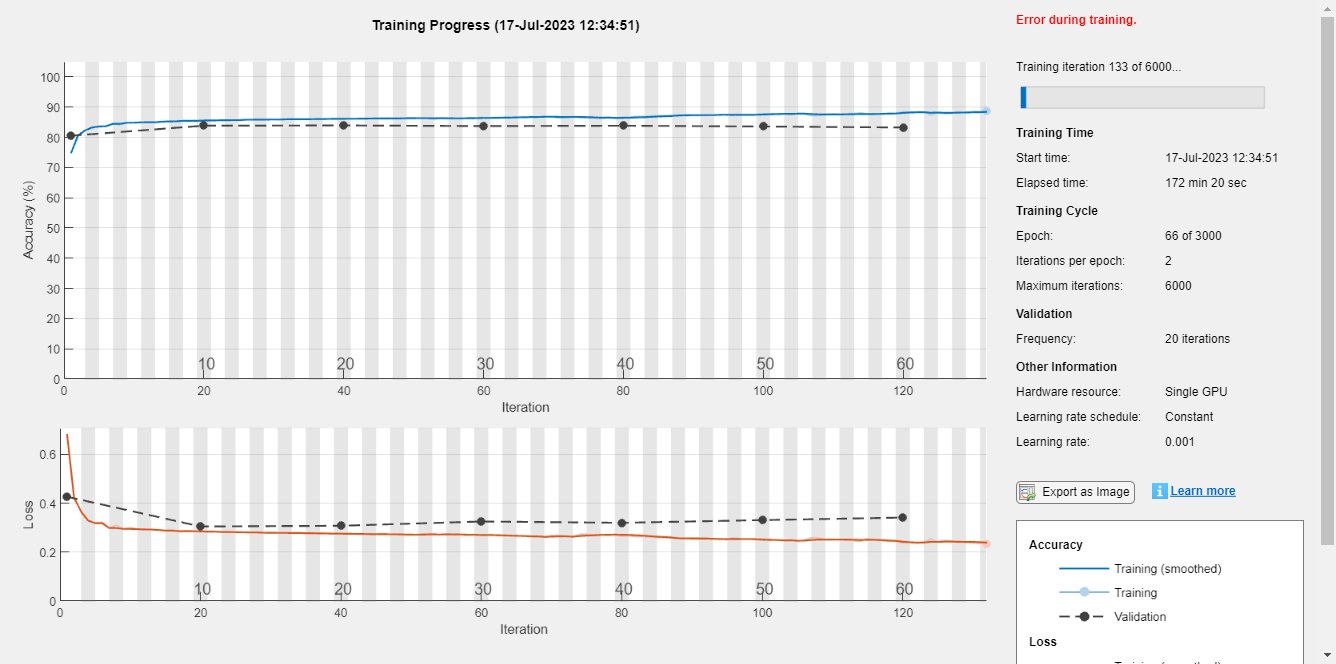

Error using trainNetwork
Unable to read file: 'C:\Users\Egco\Documents\MATLAB\makale\trainingImages2\image1009.png'.

Caused by:
    Error using matlab.io.datastore.ImageDatastore/read
    Unable to read file: 'C:\Users\Egco\Documents\MATLAB\makale\trainingImages2\image1009.png'.
        Error using matlab.io.datastore.exceptions.decorateCustomFunctionError>generateReadFcnError
        Error using ReadFcn @readDatastoreImage for file:

            C:\Users\Egco\Documents\MATLAB\makale\trainingImages2\image1009.png

        Error using <a href="ma

%training net
net =  trainNetwork(pximds, lgraph_2, options)

save mnist_28.mat

% %test code
% for k=1:12
%     idx = 1;
%     trueCheck = 0;
%     while trueCheck ~= 1
%     idx = randi(size(test.images,3));
%     if test.labels(idx) == (4)
%         trueCheck = 1;
%     end  
%     end
%     subplot(2,12,k)
%     imshow(test.images(:,:,idx)*255)
%     title("ground "+num2str(idx))
%     subplot(2,12,k+12)
%     prediction = predict(net,test.images(:,:,idx)*255);
%     imshow(prediction(:,:,1))
%     title("prediction "+num2str(idx))
% end

for k=1:12
    idx = randi(size(validationImagesNoised,3));
    subplot(2,12,k)
    imshow(validationImagesNoised(:,:,idx)*255)
    title("ground "+num2str(idx))
    subplot(2,12,k+12)
    prediction = predict(net,validationImagesNoised(:,:,idx)*255);
    imshow(prediction(:,:,1))
    title("prediction "+num2str(idx))
end